# PHASE FIELD MODELLING

## Video (Pure Melt)

clear all
format long
% Material Parameters
tic
tau =.0003;
epsilonb=.01;
mu=1;
kappa=1.8;
delta=.02;
aniso=4;
alpha=.9;
gamma=10.0;
teq=1;
theta0=pi/4;
alfa=.025

alfa =    0.025000000000000



% Grid Parameters

Nx=500;
Ny=500;
N=Nx*Ny;

dx=.03;
dy=.03;

% Time integration Parameters
n=0

n =      0



nstep=10000;
dt=1e-4;



% Nucleation

phi=zeros(Nx,Ny);
T=zeros(Nx,Ny);

% Nucleus of radius of 5 grid points at the centre of domain (Nx/2 , Ny/2)
 r=5; % radius
for i=1:Nx
    for j=1:Ny
        distance=sqrt((i)^2+(j)^2);
        if distance<r
            phi(i,j)=1;
            
        end
    end
 end

% for k=0:20:Nx
%     for i=1:Nx
%     for j=1:Ny
%         distance=sqrt((i-k)^2+(j)^2);
%         if distance<r
%             phi(i,j)=1;
%             
%         end
%     end
% end
% end

% for i=1:Nx
%     phi(i,1)=1;
%     phi(i,2)=1;
% end
% 
% for i=1:Nx
%     phi(i,Ny)=1;
%     phi(i,Ny-1)=1;
% end
% 
% for i=1:Ny
%     phi(1,i)=1;
%     phi(2,i)=1;
% end
% 
% for i=1:Ny
%     phi(Nx,i)=1;
%     phi(Nx-1,i)=1;
% end


% Create Video File

v=VideoWriter("corner1.avi");
v.FrameRate=1000 ;
open(v);



% Evolution
% Time Loop
% Applying Finite difference method



for iter=1:nstep
    
   
    lap_phi=zeros(Nx,Ny);
    lap_T=zeros(Nx,Ny);
    phi_dx=zeros(Nx,Ny);
    phi_dy=zeros(Nx,Ny);
    eps=zeros(Nx,Ny);
    d_eps=zeros(Nx,Ny);
    
    for i=1:Nx
        for j=1:Ny
            
            ip=i+1;
            im=i-1;
            
            jp=j+1;
            jm=j-1;
            
            if im==0
                im=1;
            end
            
            if ip==Nx+1
                ip=Nx;
            end
            
            if jm==0
                jm=1;
            end
            
            if jp==Ny+1
                jp=Ny;
            end
            
            % Applying 5 point stencil
            % Calculating Laplacian
            p1=phi(ip,j); % right
            p2=phi(im,j); % Left
            p3=phi(i,jp); % up
            p4=phi(i,jm); % down
            p5=phi(i,j);  % centre
            
            lap_phi(i,j)=(p1+p2+p3+p4-4*p5)/dx/dy;
            
            p1=T(ip,j); % right
            p2=T(im,j); % Left
            p3=T(i,jp); % up
            p4=T(i,jm); % down
            p5=T(i,j);  % centre
            
            lap_T(i,j)=(p1+p2+p3+p4-4*p5)/dx/dy;
            
            % Calculating gradient
            
            phi_dx(i,j)=(phi(ip,j)-phi(im,j))/2/dx;
            phi_dy(i,j)=(phi(i,jp)-phi(i,jm))/2/dy;
            
            % Theta
            
            theta=atan2(phi_dy(i,j),phi_dx(i,j));
            
            % epsilon
            
            eps(i,j)=epsilonb*(1+delta*cos(aniso*(theta-theta0)));
            
            % deps/dtheta
            
            d_eps(i,j)=-epsilonb*delta*aniso*sin(aniso*(theta-theta0));
            
        end
          
            
            
           
    end
    
    

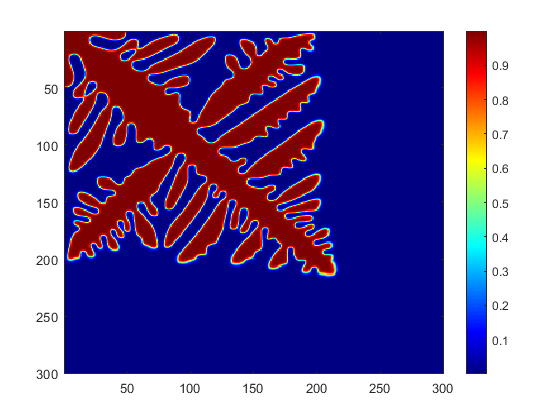

for i=1:Nx
        for j=1:Ny
            
            ip=i+1;
            im=i-1;
            
            jp=j+1;
            jm=j-1;
            
            if im==0
                im=1;
            end
            
            if ip==Nx+1
                ip=Nx;
            end
            
            if jm==0
                jm=1;
            end
            
            if jp==Ny+1
                jp=Ny;
            end
            
            % Time integration
            
            phi_old=phi(i,j);
            
            t1=(eps(i,jp)*d_eps(i,jp)*phi_dx(i,jp)-eps(i,jm)*d_eps(i,jm)*phi_dx(i,jm))/2/dy;
            
            t2=(eps(ip,j)*d_eps(ip,j)*phi_dy(ip,j)-eps(im,j)*d_eps(im,j)*phi_dy(im,j))/2/dx;
            
            m=alpha/pi*atan(gamma*(teq-T(i,j)));
            
            random = -1 + (2)*rand(1,1);
            noise=16*alfa*random*phi_old^2*(1-phi_old)^2;
            
            if iter<4000
                noise =0;
            end
            
            phi(i,j)=phi(i,j)+(dt/tau)*(t1-t2+eps(i,j)^2*lap_phi(i,j)+...
                                         phi_old*(1-phi_old)*(phi_old-.5+m)+noise);
            
            T(i,j)=T(i,j)+dt*lap_T(i,j)+kappa*(phi(i,j)-phi_old);
            
        end
end
n=n+1;

image(phi,"CDataMapping","scaled");
colormap("jet");
colorbar;
frame=getframe(gcf);

writeVideo(v,frame);

end
close(v)

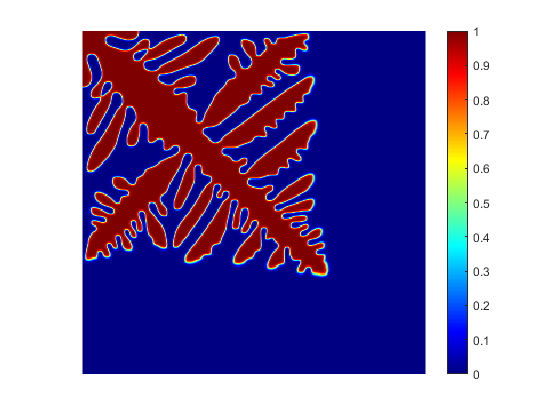

x=1:Nx;
y=1:Ny;
[X,Y]=meshgrid(x,y);
Z=griddata(x,y,phi,X,Y);
imshow(Z,"Colormap",jet)
colorbar

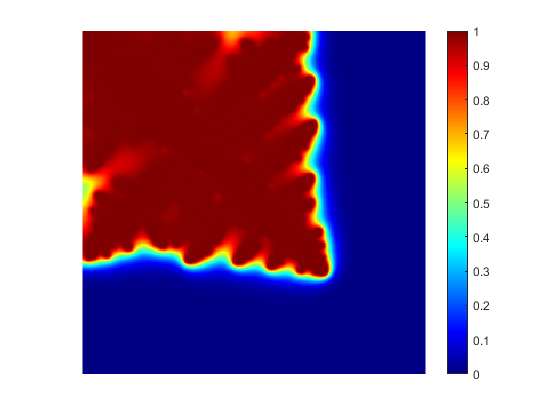




x=1:Nx;
y=1:Ny;
[X,Y]=meshgrid(x,y);
Z=griddata(x,y,T,X,Y);
imshow(Z,"Colormap",jet)
colorbar